## Create Stimulus input

% setup
clear; clc; close all; hold off; 

rng("shuffle");

c = 1; %speed of light
freqLow = 0;
freqHigh = 100;
dt = 1/100;  % delta t
tFinal = 10-dt;    % final time
t = 0 : dt: tFinal;
numChirps = 2;

%[txSig, freq, theta] = radarTriangleChirp(t, freqLow, freqHigh, numChirps);
[txSig, freq, theta] = radarSawtoothChirp(t, freqLow, freqHigh, numChirps);
%txSig = real(txSig);


## Model channel effect

Simply going to time shift the generated signal and add noise

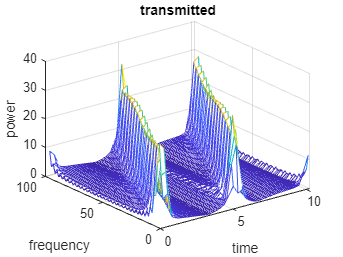

delay = 1;
sampleDelay = delay / dt;
%how to moddle doppler
rxSig = channel(txSig, .75, sampleDelay);

%generate spectrograms of original and recieved signal
fs = 1/dt;   % freq sample rate for y data f = 1/dt
nOverlap = 32;      % number samples for window overlap
nfft = 2^(nextpow2(length(t)));   % how many samples of y to use for spectrogram
windowLen = 64; %choose power of 2
window = transpose(rectwin(windowLen) * ones(1, nfft));   % simple rect window 32 samp long (maybe change to hann etc?)
[txFft, txFftFreq, txFftTime] = dtft(txSig, fs, windowLen, nOverlap);
mesh(txFftTime, txFftFreq, abs(txFft));
title("transmitted");xlabel("time"); ylabel("frequency"); zlabel("power");

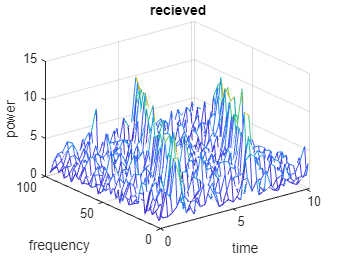

[rxFft, rxFftFreq, rxFftTime] = dtft(rxSig, fs, windowLen, nOverlap);
mesh(rxFftTime, rxFftFreq, abs(rxFft));
title("recieved");xlabel("time"); ylabel("frequency"); zlabel("power");

## Instantanous frequency difference

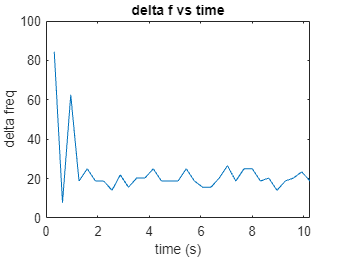

% finds maximum power at each window and its corresponding frequency bin
[txFftMax, txFreqIndex] = max(txFft, [], 1);
txFreq = txFftFreq(txFreqIndex);
[rxFftMax, rxFreqIndex] = max(rxFft, [], 1);
rxFreq = rxFftFreq(rxFreqIndex);

freqDiff = mod( txFreq - rxFreq,  freqHigh - freqLow);
plot(txFftTime, freqDiff);
title("delta f vs time")
ylabel("delta freq");
xlabel("time (s)");

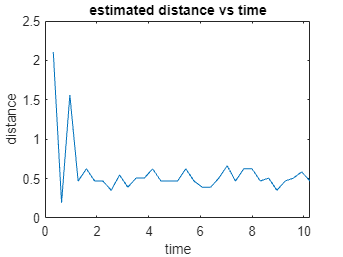


txDf_Dt = (freqHigh - freqLow) * numChirps / tFinal;
deltaT = freqDiff / txDf_Dt;
dist = c * deltaT/2;
 
plot(txFftTime, dist);
title ("estimated distance vs time")
xlabel("time");
ylabel("distance");

%}

function [sigFft, sigFftFreq, sigFftTime] = dtft(signal, fs, windowLen, nOverlap)
    

    buffered = buffer(signal, windowLen, nOverlap); % [windowLen, frame]
    sigFft = fft(buffered);
    nt = 1:1:size(sigFft, 2);    % count number of time instants in txFft
    nw = 1:1:windowLen;          % count number of freq bins in txFft
    frameDt = (windowLen - nOverlap)*1/fs; %elapsed time between frames in fft
    frameDf = fs / windowLen; 
    sigFftTime = nt * frameDt; % waterfall axis of fft times
    sigFftFreq = nw * frameDf;  
end
